## System Identification for Arduino Engineering Kit Motors

% Continous time domain for Left Motor

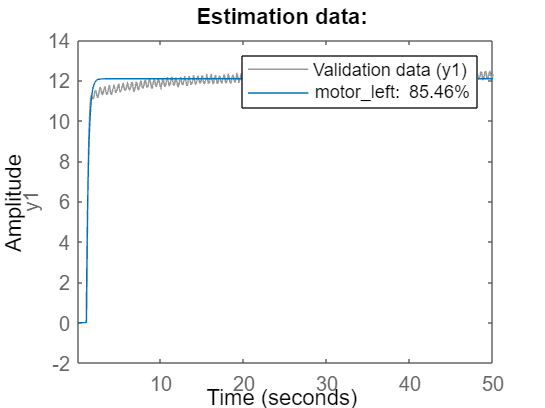

% Create object for time series data
estimationData = iddata(y_wL,u,0.01);
validationData = iddata(y_wL_50,u_50,0.01);

% Estimate process model
motor_left = procest(estimationData,'P1');

% Display results
compare(estimationData,motor_left);
clear estimationData;
title('Estimation data:');

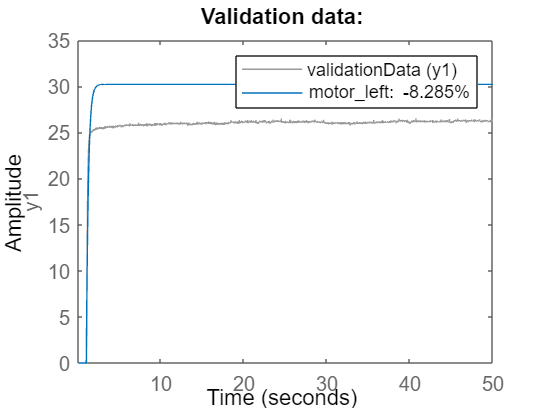

figure;
compareplot(validationData,motor_left);
clear validationData;
title('Validation data:');

% Continous time domain for Right Motor

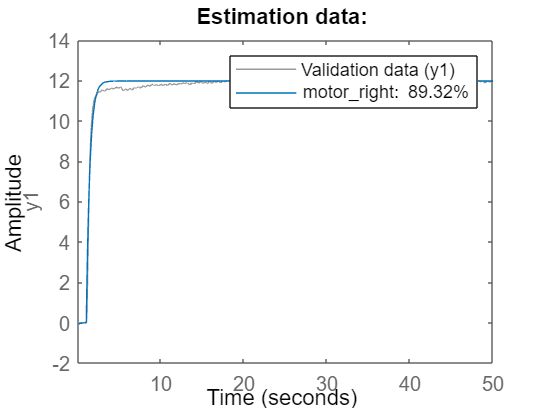

% Create object for time series data
estimationData2 = iddata(y_wR,u,0.01);
validationData2 = iddata(y_wR_50,u_50,0.01);

% Estimate process model
motor_right = procest(estimationData2,'P1');

% Display results
compare(estimationData2,motor_right);
clear estimationData2;
title('Estimation data:');

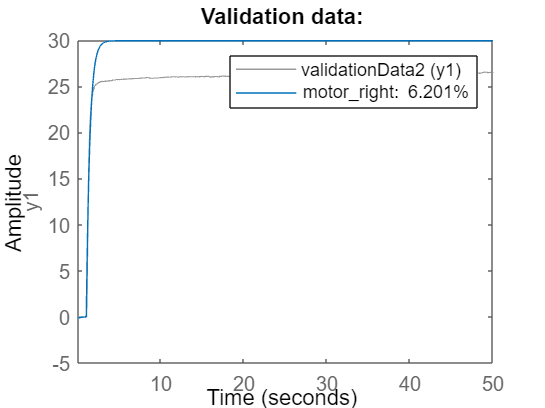

figure;
compareplot(validationData2,motor_right);
clear validationData2;
title('Validation data:');